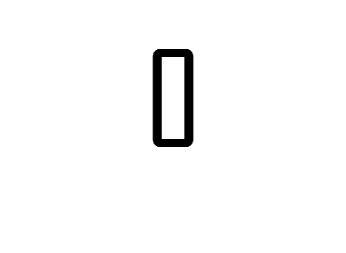

% Image loading and dataset split
% img = readimage(imds,1);
% size(img)

numTrainFiles = 762;
numTestFiles = 254;
trainpath = fullfile('./dataset/train');
testpath = fullfile('./dataset/test');
imdsTrain = imageDatastore(trainpath, 'IncludeSubfolders', true, 'LabelSource', 'foldernames');
imdsTest = imageDatastore(testpath, 'IncludeSubfolders', true, 'LabelSource', 'foldernames');
[imdsTrain, imdsValidation] = splitEachLabel(imdsTrain, numTrainFiles, 'randomized');

% augmentation function
function img = randomAugmentation(img)
    % Randomly apply negative effect
    if rand > 0.5
        img = 255 - img;
    end

    % Randomly apply salt & pepper noise
    if rand > 0.5
        img = imnoise(img, 'salt & pepper', 0.02);
    end
end

% imdsTrain.ReadFcn = @(loc)randomAugmentation(imresize(imread(loc), [128, 128]));

taskpath = fullfile('./dataset/task');
imdsTask = imageDatastore(taskpath, 'IncludeSubfolders', true, 'LabelSource', 'foldernames');

trainSetDetail = countEachLabel(imdsTrain);
testSetDetail = countEachLabel(imdsTest);

img = readimage(imdsTrain,1);
figure;
imshow(img);

size(img)

ans =    128   128


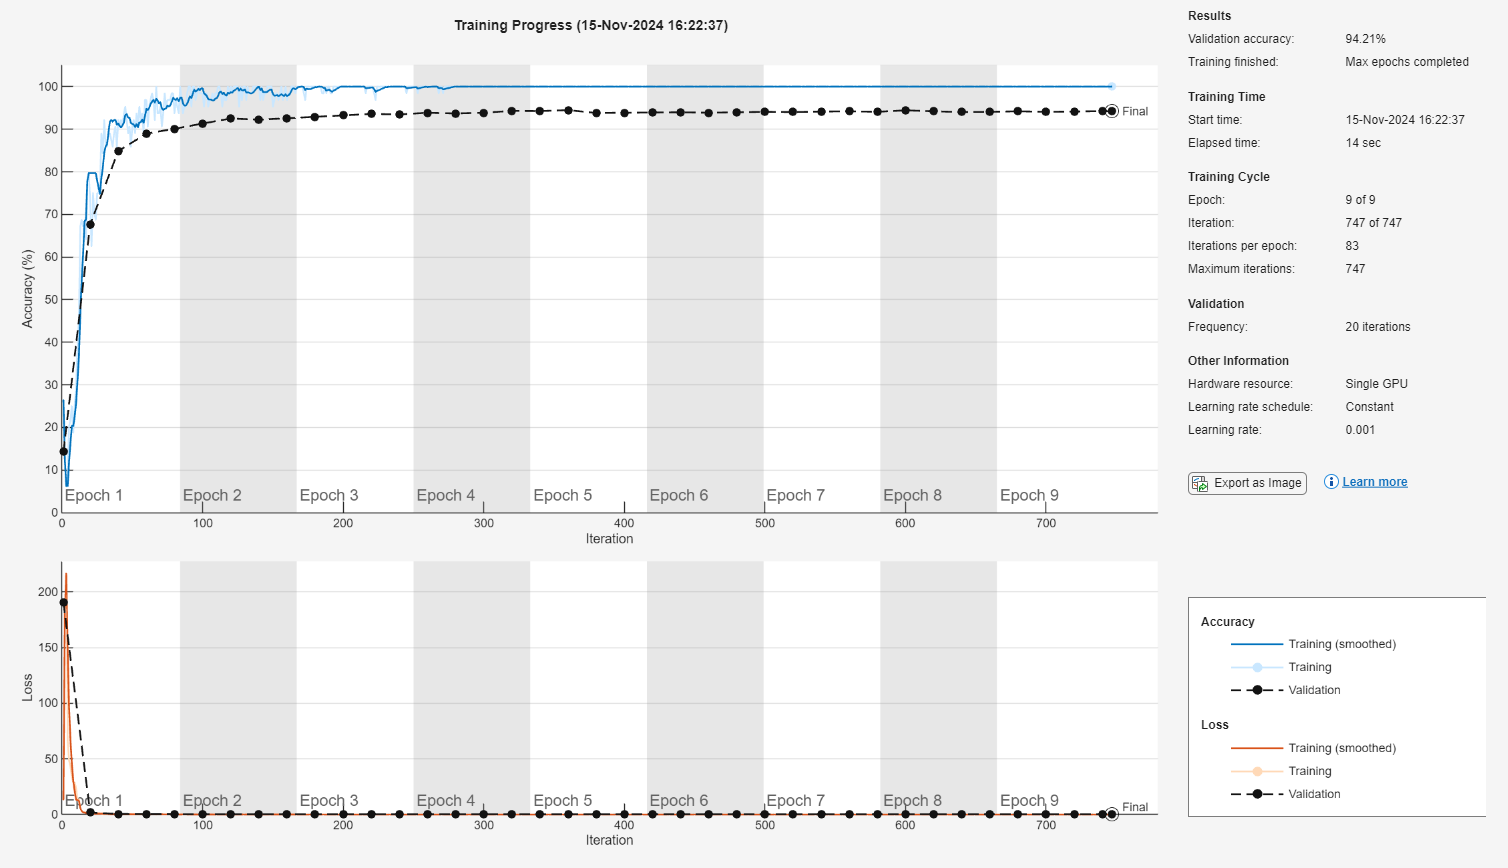


% CNN Architecture
layers = [
    imageInputLayer([128 128 1]) % 输入图像层，128x128x1
    
    % 第一层卷积层
    convolution2dLayer(5, 6, 'Padding', 'same', 'Stride', 1) % 卷积核5x5，6个滤波器
    reluLayer() % 激活函数
    maxPooling2dLayer(2, 'Stride', 2) % 最大池化，2x2，步长2

    % 第二层卷积层
    convolution2dLayer(5, 16, 'Padding', 'same', 'Stride', 1) % 卷积核5x5，16个滤波器
    reluLayer() % 激活函数
    maxPooling2dLayer(2, 'Stride', 2) % 最大池化，2x2，步长2

    % 第三层全连接层
    fullyConnectedLayer(120) % 全连接层，120个神经元
    reluLayer() % 激活函数

    % 第四层全连接层
    fullyConnectedLayer(84) % 全连接层，84个神经元
    reluLayer() % 激活函数

    % 输出层
    fullyConnectedLayer(7) % 输出全连接层，7个分类
    softmaxLayer() % Softmax层
    classificationLayer() % 分类输出层
];
analyzeNetwork(layers);

% Training Options
options = trainingOptions('adam', ...
    'InitialLearnRate', 0.001, ...
    'MaxEpochs', 9, ...
    'Shuffle', 'every-epoch', ...
    'ValidationData', imdsTest, ...
    'ValidationFrequency', 20, ...
    'MiniBatchSize', 64, ...
    'Verbose', false, ...
    'ExecutionEnvironment', 'auto', ...
    'Plots', 'training-progress');

% Training the Network
net = trainNetwork(imdsTrain, layers, options);

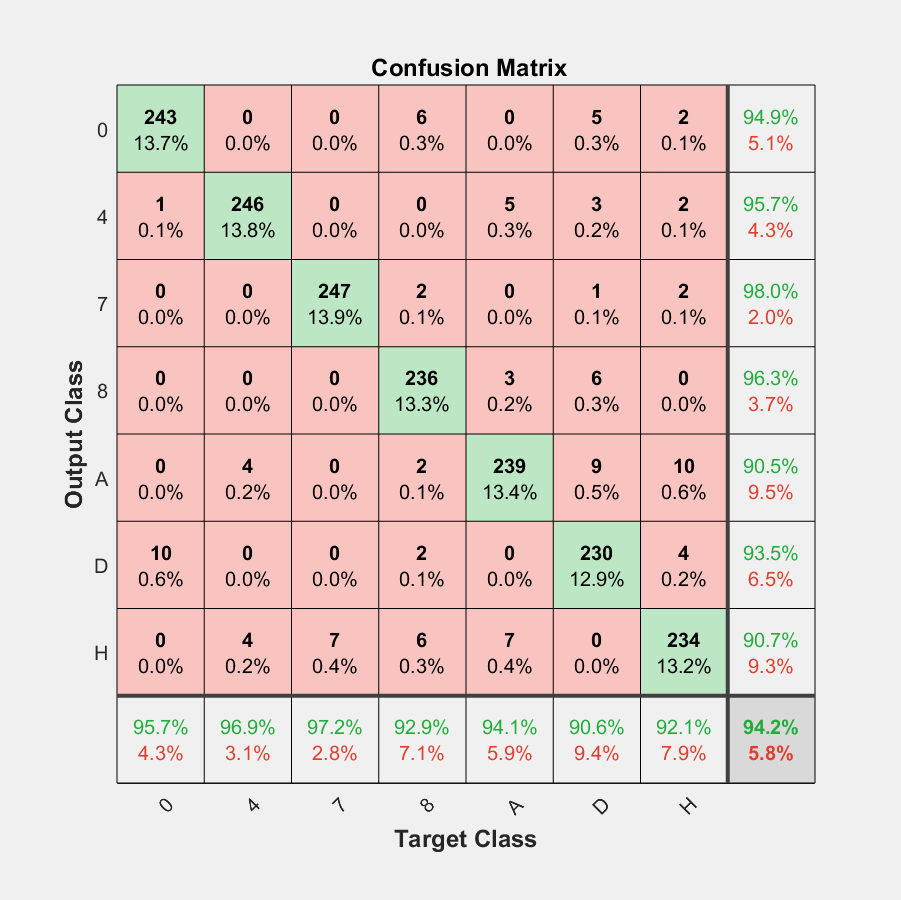

YPred = classify(net, imdsTest);
YTest = imdsTest.Labels;

% Accuracy Calculation
accuracy = sum(YPred == YTest) / numel(YTest);

% Confusion Matrix Display
confMat = confusionmat(YTest, YPred);
% MhelperDisplayConfusionMatrix(confMat)
plotconfusion(YTest, YPred);

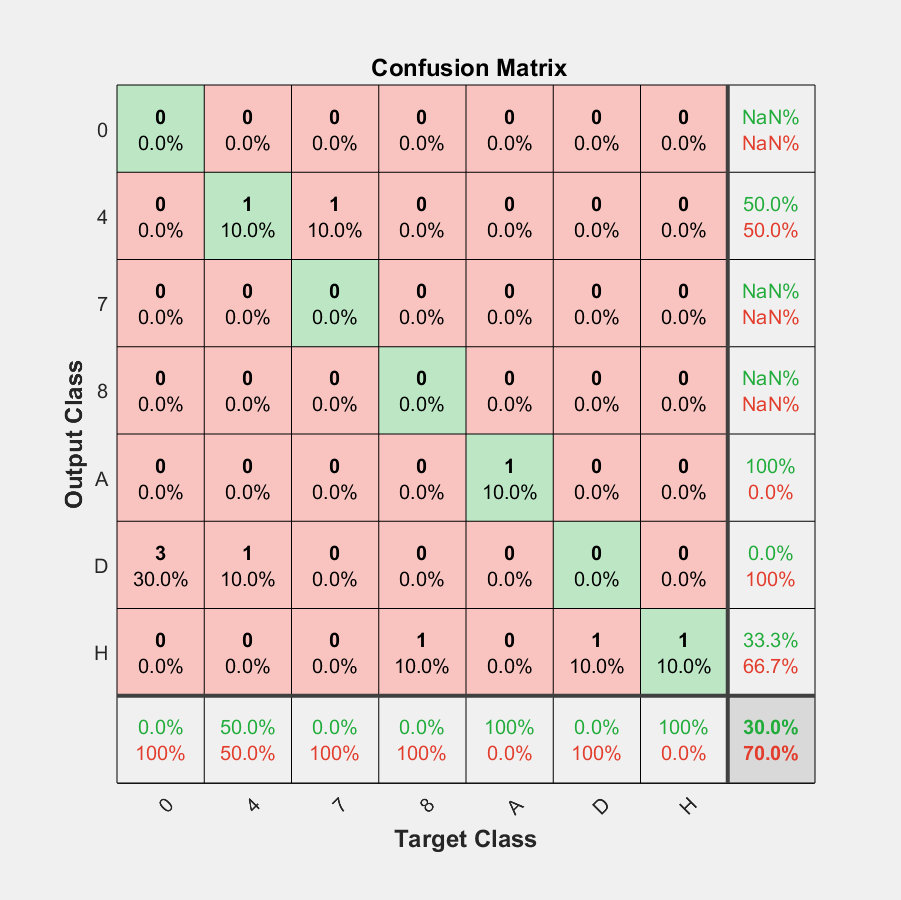


% Task Prediction
imdsTask.ReadFcn = @(loc)im2gray(imresize(imread(loc), [128, 128]));
YTaskpredict = classify(net, imdsTask);
YTrue = imdsTask.Labels;
accuracy = sum(YTaskpredict == YTrue) / numel(YTrue); 
% figure;
confMatTask = confusionmat(YTrue, YTaskpredict);
% MhelperDisplayConfusionMatrix(confMatTask);
plotconfusion(YTrue, YTaskpredict);